clear
Freqs = CleanDir('C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\RawFreq');

Behaviors = CleanDir('C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\StableDoubleNegQ');

Deci.Analysis.Freq.Extra.Corr.Behavior = {'NegPun2Q\mEV' 'NegPun2Q\mPE' 'NegPun2Q\mR' 'NegPun2Q\mEV_next' ...
                                          'NegPun2Q\sEV' 'NegPun2Q\sPE' 'NegPun2Q\sR' 'NegPun2Q\sEV_next' 'NegPun2Q\alpha'};
Deci.Analysis.Freq.Extra.Corr.categorical = [5:8];
Deci.Analysis.Freq.Extra.Corr.signed = [5:8];

%x + x4*x9 + x3*x8 x1*x6 + + x3*x8-x8 + x1*x6
states = [20 21 23 24 120 121];

for subj = 1:length(Freqs)

    load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\RawFreq_2\' Freqs{subj} '\Fdb Onset\All\FCz.mat']);

    data{subj} = cat(1,rawfreq.trialpow{:});

    load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\RawFreq\' Freqs{subj} '\Stim Onset\All\FCz.mat']);

    bsl{subj} = nanmean(cat(1,rawfreq.trialpow{:}),1);

    data{subj} = [data{subj} - bsl{subj}]./bsl{subj};
    %data{subj} = [data{subj} - bsl{subj}]; %./bsl{subj};

    b = load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\NegPun2Q\S\' filesep Freqs{subj} '\All.mat']);


    for behv = 1:length(Deci.Analysis.Freq.Extra.Corr.Behavior)

        load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\' Deci.Analysis.Freq.Extra.Corr.Behavior{behv} filesep Freqs{subj} '\All.mat']);

        bparam{behv} = cat(2,param{:})';
        bparam{behv} = bparam{behv}(rawfreq.trials);
        if ismember(behv,Deci.Analysis.Freq.Extra.Corr.signed)
        bparam{behv}(bparam{behv} == -1) = 2;
        bparam{behv}(bparam{behv} == 0) = 1;
        end

        for stat = 1:length(states)

            blk = 1;
            for block = 1:length(b.param)

               

                if ismember(states(stat),b.param{block})
                   pos = ismember(b.param{block},states(stat));

                   blkparam{behv}(stat,subj,blk,:) = nan([40 1]);

                   blkparam{behv}(stat,subj,blk,:) = [param{block}(pos) nan([1 40-length(param{block}(pos))])];

                   blk = blk + 1;
                else
                    continue
                end

            end
            
        end


    end

    behav{subj} = cat(2,bparam{:});

end

brain = cat(1,data{:});
behavior = cat(1,behav{:});

BehvTitles = {'mEV' 'mPe' 'mR', 'mEV_next'...
             'sEV' 'sPe' 'sR','sEV_next','alpha','brain'};

%Deci.Analysis.Freq.Extra.Corr.formula = 'brain ~ 1  + mPe*sPe  + mR*sR' + mR + sR;

Deci.Analysis.Freq.Extra.Corr.formula = 'brain ~ 1 + mR*sR +  mPe*sPe + alpha:mPe:sPe';
BBCorr = array2table([behavior brain],'VariableNames',BehvTitles);


mdl = fitlm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)

mdl = Linear regression model:
    brain ~ 1 + mPe*sPe + mR*sR + mPe:sPe:alpha

Estimated Coefficients:
                        Estimate         SE         tStat        pValue  
                       ___________    _________    ________    __________

    (Intercept)            0.11339     0.018896       6.001    2.0086e-09
    mPe                  0.0058917    0.0016425       3.587    0.00033568
    mR                 -0.00016802    0.0014139    -0.11883       0.90541
    sPe_2                -0.017549     0.029873    -0.58744       0.55691
    sR_2                   0.11429     0.052128      2.1925      0.028361
    mPe:sPe_2             0.013228    0.0030418      4.3487     1.379e-05
    mR:sR_2             -0.0041738     0.004264 

% mdl2 = stepwiselm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical,'PEnter',0)
% mdl3 = stepwiselm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)
% mdl4 = stepwiselm(BBCorr,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)
% 
% mdl5 = stepwiselm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical,'Criterion','aic')

% 
% Deci.Analysis.Freq.Extra.Corr.Behavior = {'StableDoubleNegQ\mEV' 'StableDoubleNegQ\mPE' 'StableDoubleNegQ\mEV_next' 'StableDoubleNegQ\maEV' 'StableDoubleNegQ\mR' ...
%                                           'StableDoubleNegQ\sEV' 'StableDoubleNegQ\sPE' 'StableDoubleNegQ\sEV_next' 'StableDoubleNegQ\saEV' 'StableDoubleNegQ\sR'};

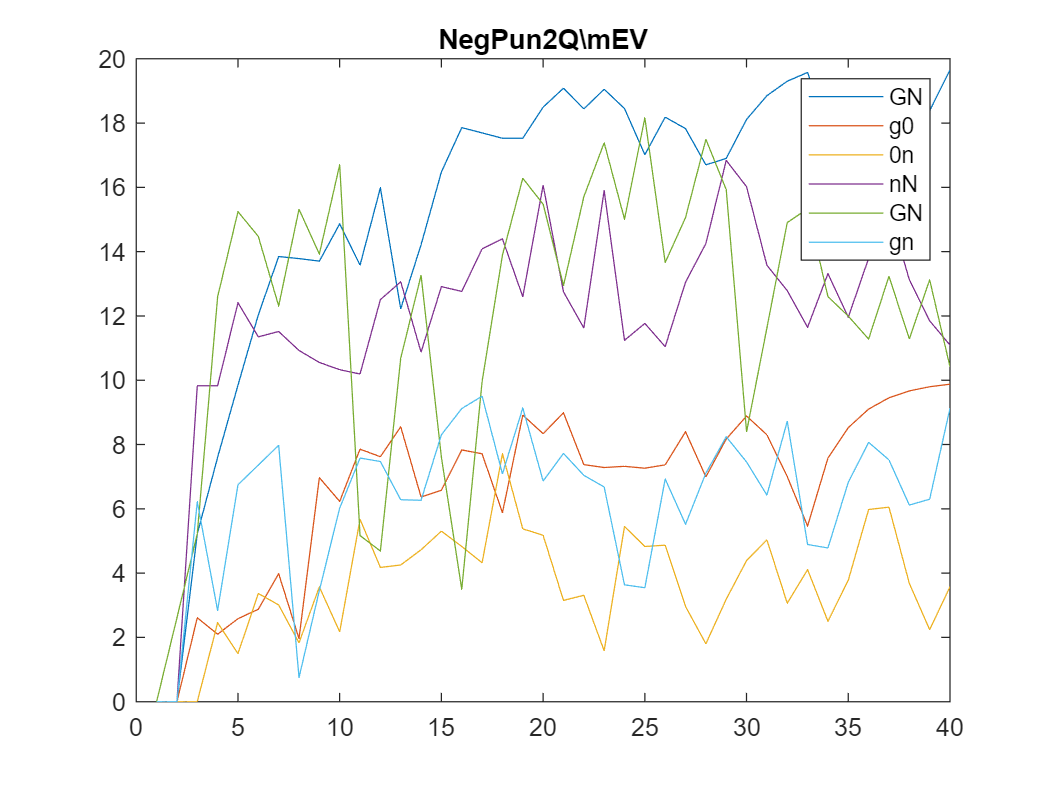

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


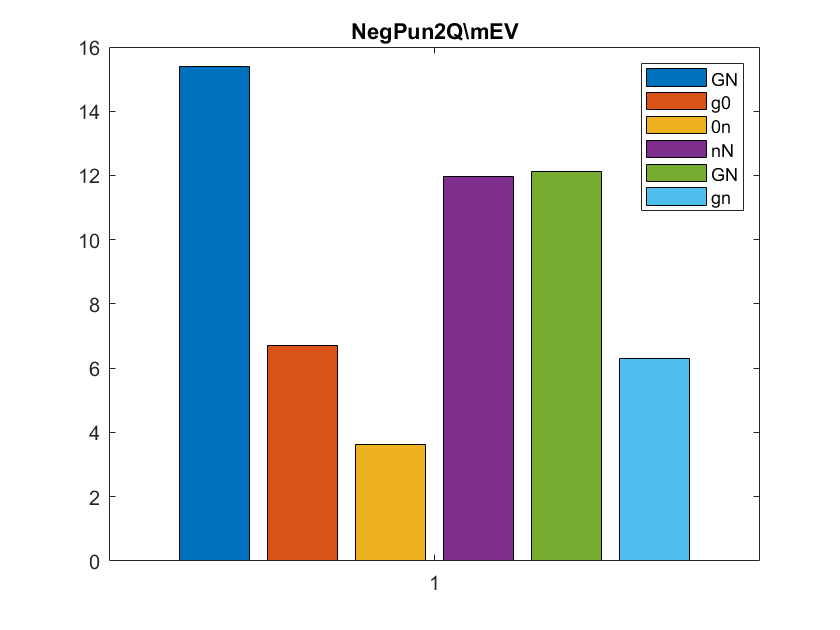

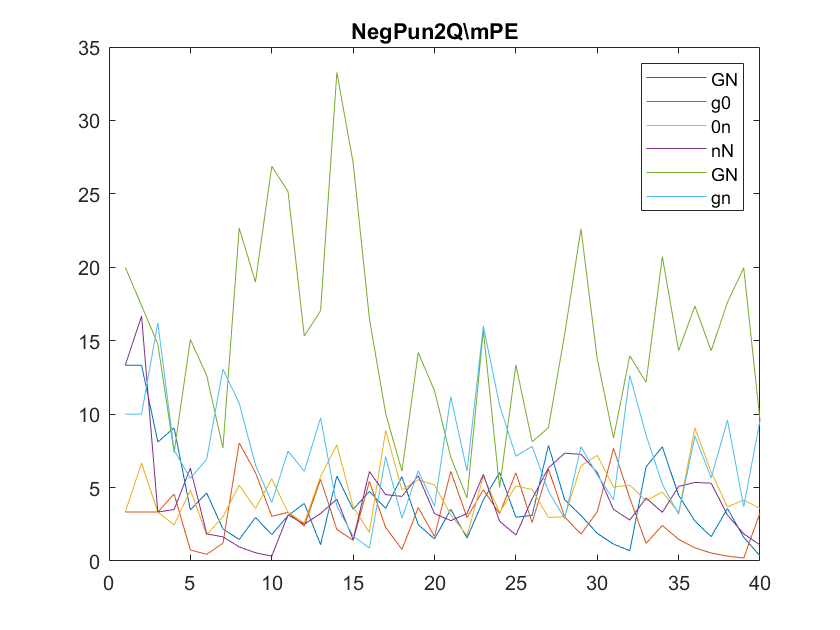

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


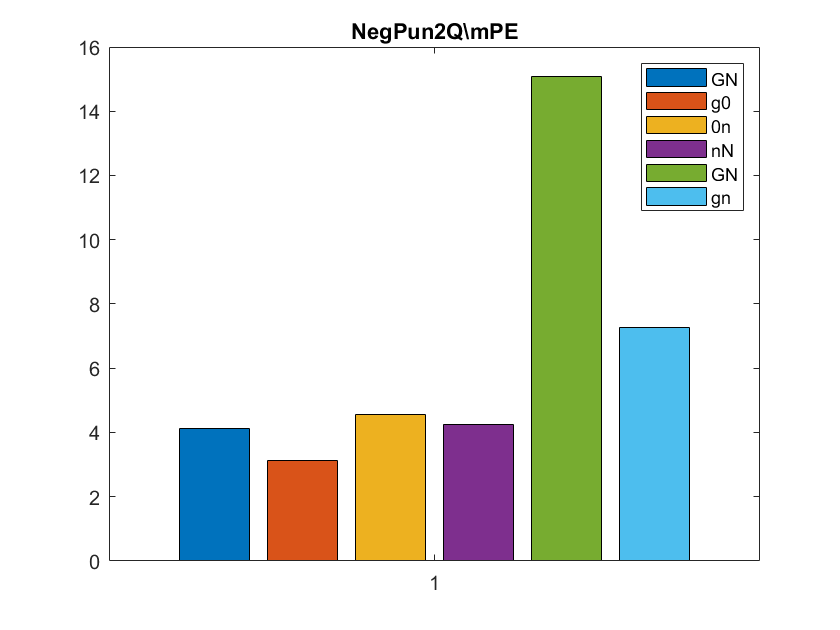

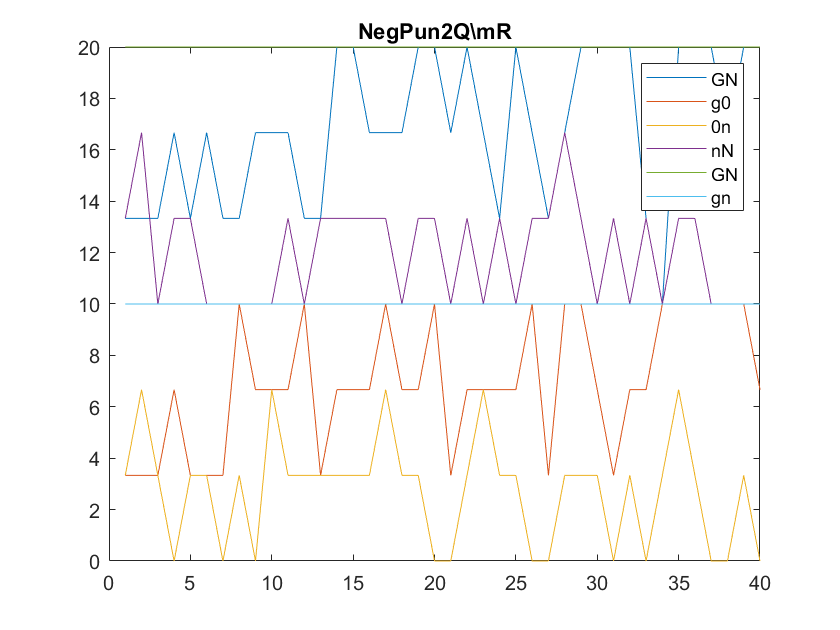

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


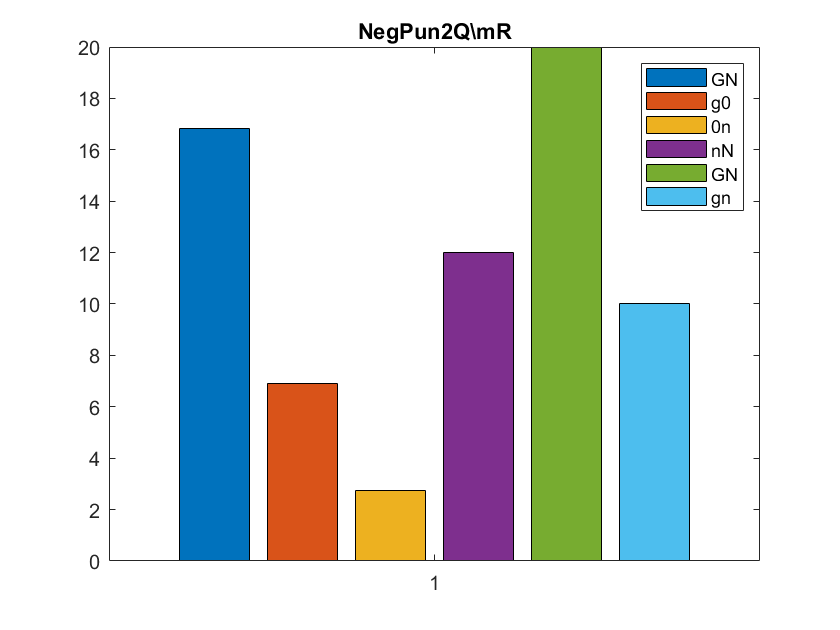

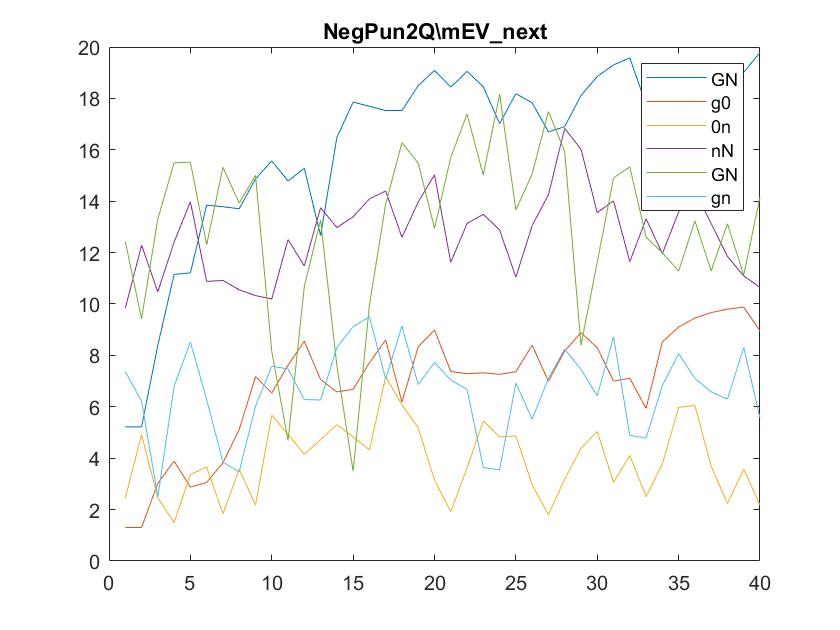

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


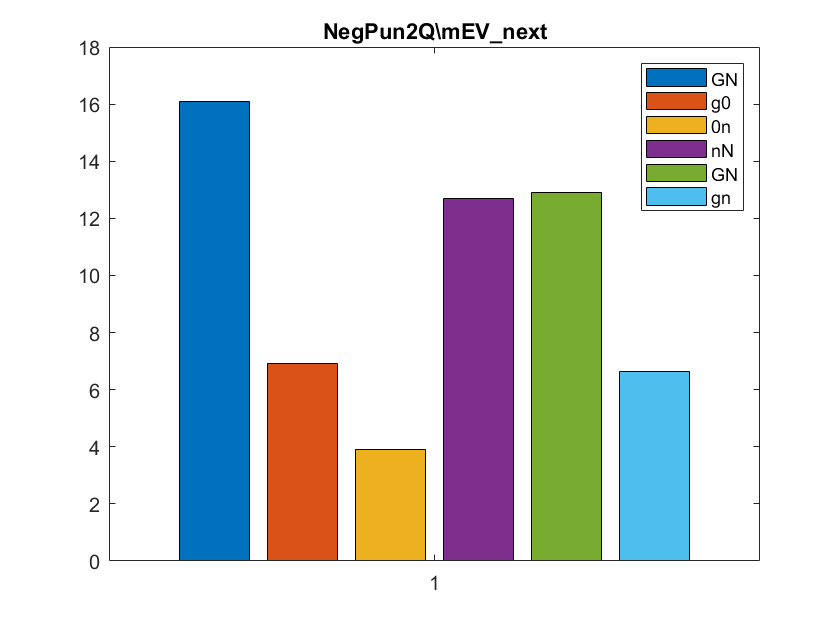


statenames = {'Gg' 'g0' '0n' 'nN' 'GN' 'gn'};
for blk = 1:length(blkparam)

    dat = squeeze(nanmean(nanmean(blkparam{blk},2),3));

    figure;
    plot(dat')
    title(Deci.Analysis.Freq.Extra.Corr.Behavior{blk})
    legend(statenames)

    figure;
    dat = squeeze(nanmean(nanmean(nanmean(blkparam{blk},2),3),4));
    CleanBars(dat')
    title(Deci.Analysis.Freq.Extra.Corr.Behavior{blk})
    legend(statenames)
end


BehvTitlesInt = {'mEV:sEV' 'mPe:sPe' 'mR:sR', 'mEV_next:sEV_next'};

for blk = 1:4

    dat = squeeze(nanmean(nanmean(blkparam{blk},2),3)).*squeeze(nanmean(nanmean(blkparam{blk+4},2),3));
    figure;
    plot(dat')
    title(BehvTitlesInt{blk})
    legend(statenames)

    figure;
    dat = squeeze(nanmean(nanmean(nanmean(blkparam{blk},2),3),4)).*squeeze(nanmean(nanmean(nanmean(blkparam{blk+4},2),3),4));
    CleanBars(dat')
    title(BehvTitlesInt{blk})
    legend(statenames)

end

Index exceeds the number of array elements. Index must not exceed 4.